# Control and Instrumentation Lab Assignment 3

**SWARNENDU PAUL 19EE3FP18**

**Question 2.**

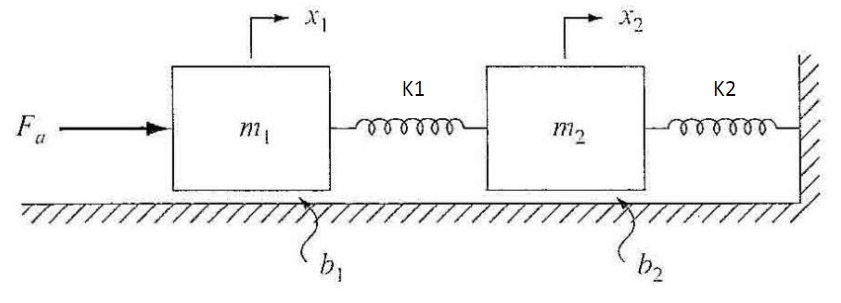

For the given spring block system,

Balancing forces in $m_1$ we get,


$$F_a - b_1\dot{x_1} - k_1(x_1-x_2) = m_1\ddot{x_1}$$


and balancing forces in $m_2$ we get,


$$k_1(x_1-x_2) - b_2\dot{x_2} - k_2x_2 = m_2\ddot{x_2}$$
 

we can define 4 variables $q_1 = x_1$, $q_2=\dot{x_1}$, $q_3=x_2$, $q_4=\dot{x_2}$

So we get,


$$\dot{q_1} = 0\cdot q_1+1\cdot q_2+0\cdot q_3 +0\cdot q_4+0\cdot F_a$$



$$\dot{q_2} = -\frac{k_1}{m_1}\cdot q_1-\frac{b_1}{m_1}\cdot q_2+\frac{k_1}{m_1}\cdot q_3+0\cdot q_4+\frac{1}{m_1}\cdot F_a$$



$$\dot{q_3} = 0\cdot q_1+0\cdot q_2+0\cdot q_3 +1\cdot q_4+0\cdot F_a$$



$$\dot{q_4} = \frac{k_1}{m_2}\cdot q_1+0\cdot q_2-\frac{(k_1+k_2)}{m_2}\cdot q_3-\frac{b_2}{m_2}\cdot q_4+0\cdot F_a$$


As given in question we need transfer function from $F_a$ to $x_2$.

So our state space representation matrices will be,


$$A=[0,1,0,0;-\frac{k_1}{m_1},-\frac{b_1}{m_1},\frac{k_1}{m_1},0;0,0,0,1;\frac{k_1}{m_2},0,-\frac{(k_1+k_2)}{m_2},-\frac{b_2}{m_2}]$$



$$B = [0;\frac{1}{m_1};0;0]$$



$$C = [0,0,1,0]$$


D = 0

Lets save the value of variables first

m1=1; k1=1; b1=0.1; m2=2; k2=1.5; b2=0.2;

Now we define the matrices we need to calculate tf from ss

A=[0,1,0,0;-k1/m1,-b1/m1,k1/m1,0;0,0,0,1;k1/m2,0,-(k1+k2)/m2,-b2/m2];
B=[0;1/m1;0;0];
C=[0,0,1,0];
D=0;

Now we can find the transfer function from $F_a$ to $x_2$

[b,a]=ss2tf(A,B,C,D);

So the transfer function is

tf1=tf(b,a)

tf1 =
 
                     0.5
  -----------------------------------------
  s^4 + 0.2 s^3 + 2.26 s^2 + 0.225 s + 0.75
 
Continuous-time transfer function.



Now the unit step response is shown in the plot.

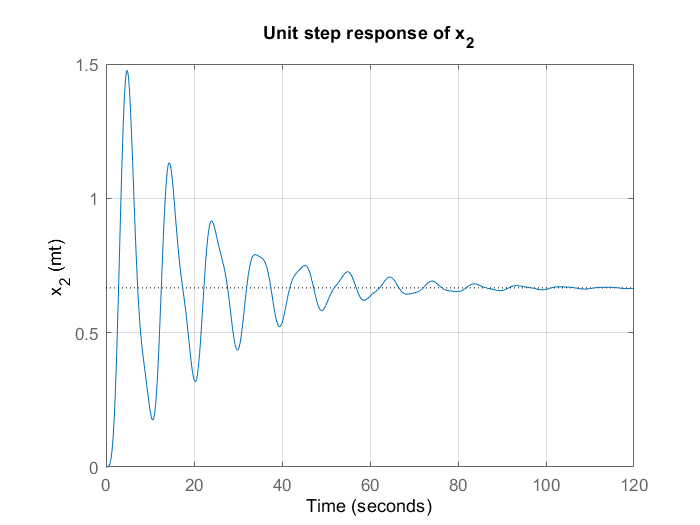

figure
step(tf1)
title("Unit step response of x_2")
grid on
ylabel("x_2 (mt)")

Because of the applied force the 2nd box starts moving from it's initial position and due to damping force applied it eventually becomes constant at 0.5mt. where forces applied on both blocks are balanced.

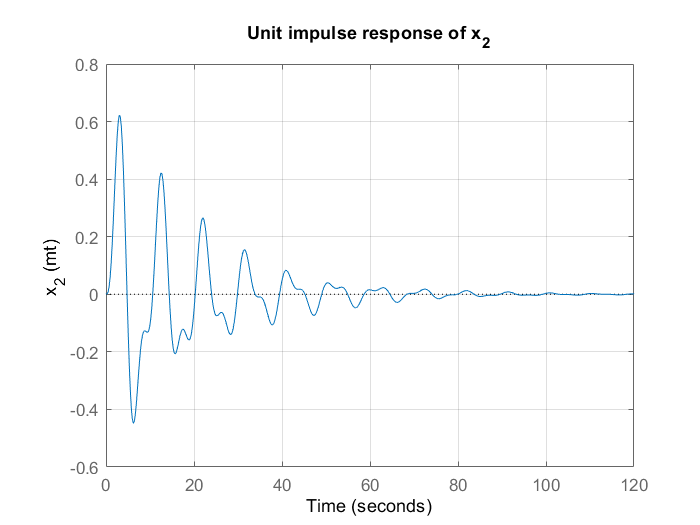

figure
impulse(tf1)
title("Unit impulse response of x_2")
grid on
ylabel("x_2 (mt)")

Here, due to unit impulse at t=0 the block starts oscillating but eventually the amplitude reduces due to damping.

Now we will find the plot of $x_2$ when a sinusoidal force $F_a(t)=sin(\frac{2\pi t}{3})$is applied(T=3sec)

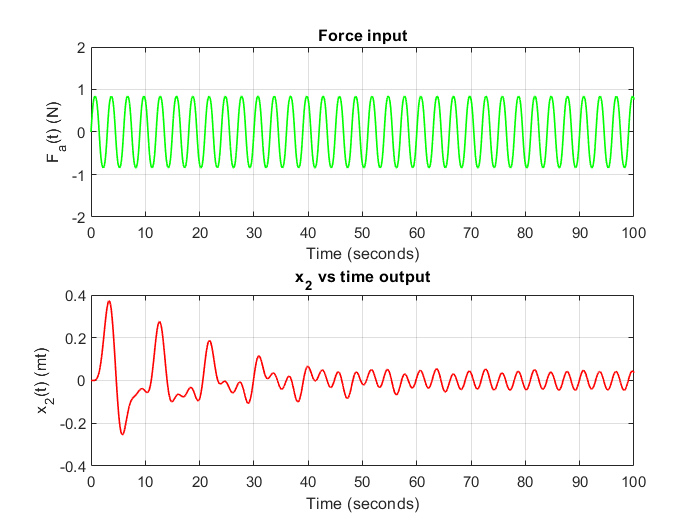

figure
t=0:1e-3:100;
u=sin(sin(2*pi*t/3));
[x2_out,tout]=lsim(tf1,u,t);
subplot(2,1,1)
plot(t,u,"LineWidth",1,"Color","g");
title("Force input");
ylabel("F_a(t) (N)");
xlabel("Time (seconds)");
ylim([-2,2]);
grid on
subplot(2,1,2)
plot(tout,x2_out,"LineWidth",1,"Color","r")
title("x_2 vs time output");
ylabel("x_2(t) (mt)");
xlabel("Time (seconds)");
grid on

Now, the same dynamical system is simulated in SIMULINK. The simulink model is saved as **springblock.slx**

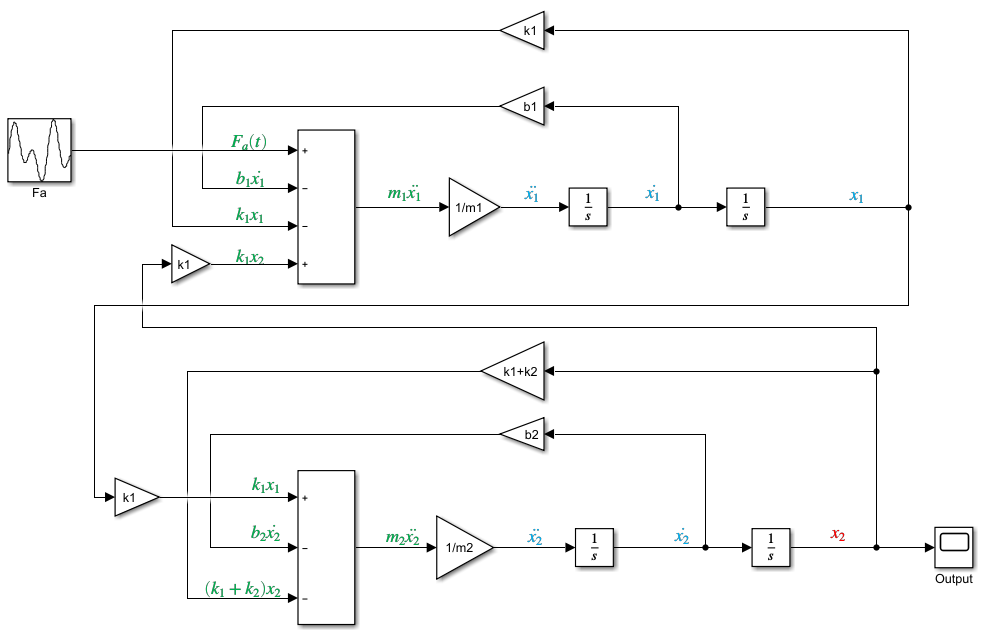

Applying an unit step output from the waveform generator gives the following output

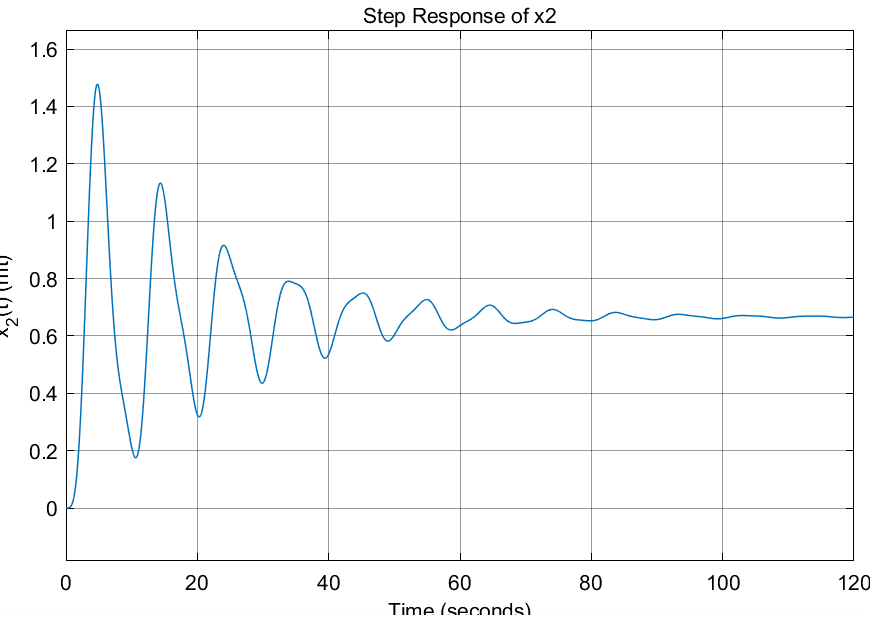

Which is same as the step response we generated from transfer function.

Applying an unit impulse output from the waveform generator gives the following output

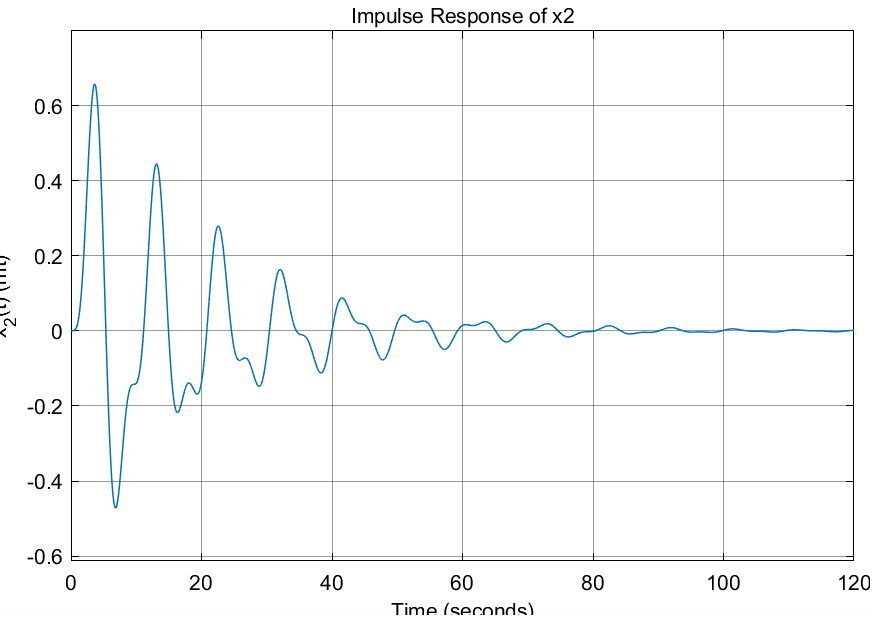

Which is same as the unit impulse response generated from transfer function.

Applying a sinusoidal output of time period 3 sec from the waveform generator gives the following output,

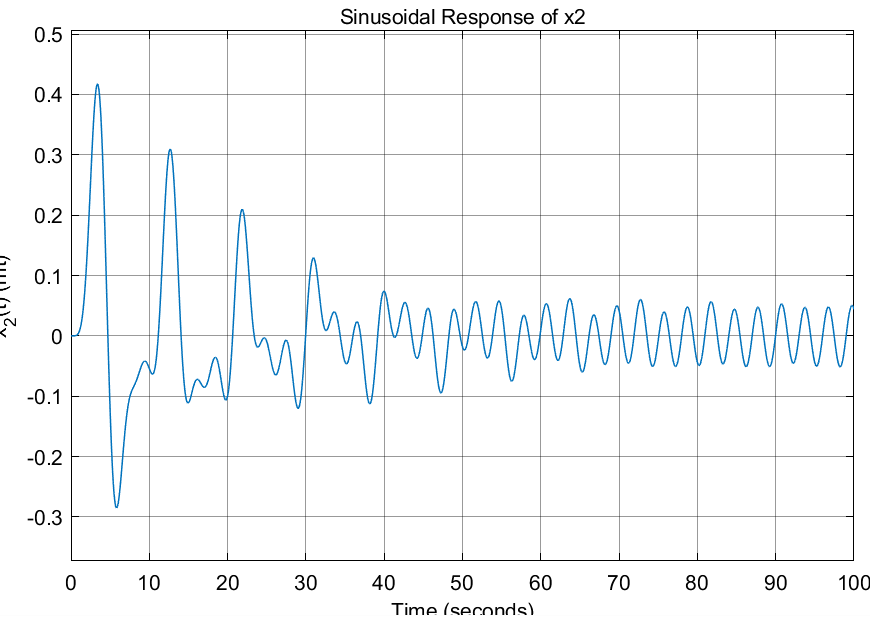

So, all the responses derived from transfer function is verified to be true from the simulink model.

**Question 3**

**A.**

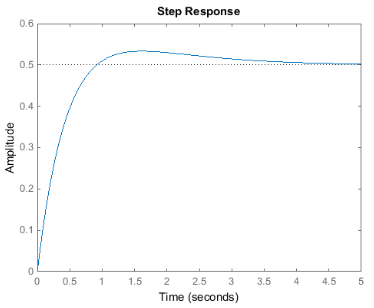

The step response shown in the diagram has no oscillatory behaviour but it has an overshoot. So, this system may be overdamped or critically damped system. Also the overshoot signifies a presence of zero in the system, which is negative as it amplifies the initial response so that the response reaches the equilibrium quicker and while doing so, the overshoot happens.

So, the form of the transfer function can be a **Overdamped **or **Critically damped system **with **one negative zero.**

For example,

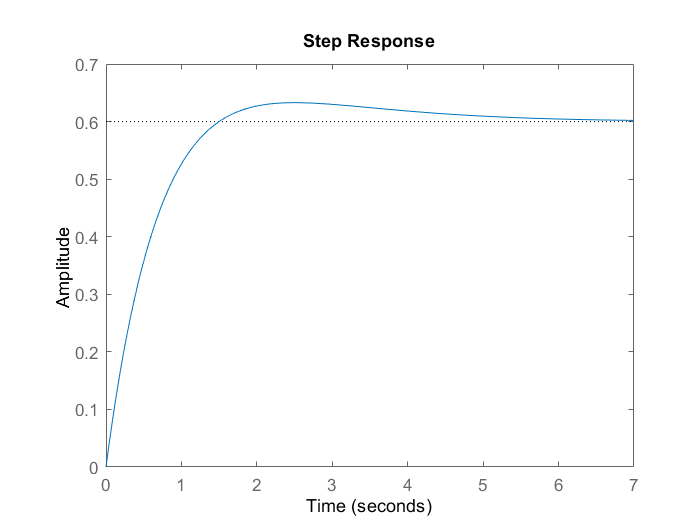

figure
step([1,0.6],[1,2,1])

A critically damped system with poles [-1,-1] and zero -0.6

**B.**

Yes, we can observe overshoot in over-damped 2nd order system, if the system has **a negative zero** which amplifies the initial response and may cause an overshoot.

for example,

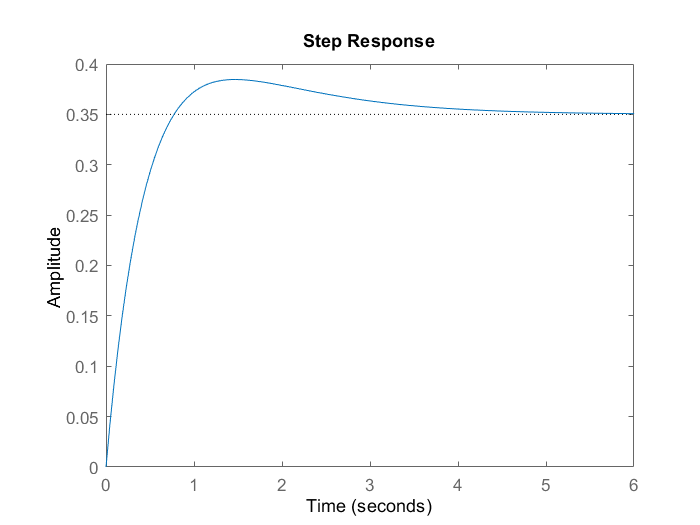

figure
step([1,0.7],[1,3,2])

An overdamped system with poles [-1,-2] and zero -0.7